unzip('midterm.zip', 'unzipped_data');

% Define the dataset folder
datasetPath = fullfile(pwd, 'unzipped_data');

% Define paths to each set
trainPath = fullfile(datasetPath, 'train');
valPath   = fullfile(datasetPath, 'validation');
testPath  = fullfile(datasetPath, 'test');

% Load datastores
imdsTrain = imageDatastore(trainPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsVal = imageDatastore(valPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsTest = imageDatastore(testPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Show image counts
fprintf('✅ Training Images:   %d\n', numel(imdsTrain.Files));

✅ Training Images:   3110


fprintf('✅ Validation Images: %d\n', numel(imdsVal.Files));

✅ Validation Images: 350


fprintf('✅ Test Images:       %d\n', numel(imdsTest.Files));

✅ Test Images:       358


%% Step 2: Resize and Extract HOG Features for All Sets

inputSize = [128 128];  % Resize all images to 128x128
hogFeatureSize = length(extractHOGFeatures(zeros(inputSize)));  % Get HOG feature vector length

% Count images
numTrain = numel(imdsTrain.Files);
numVal   = numel(imdsVal.Files);
numTest  = numel(imdsTest.Files);

% Preallocate feature matrices
featuresTrain = zeros(numTrain, hogFeatureSize);
featuresVal   = zeros(numVal, hogFeatureSize);
featuresTest  = zeros(numTest, hogFeatureSize);

% --- Extract TRAIN features ---
for i = 1:numTrain
    img = imread(imdsTrain.Files{i});
    img = imresize(img, inputSize);
    if size(img, 3) == 3  % RGB -> Grayscale
        img = rgb2gray(img);
    end
    featuresTrain(i, :) = extractHOGFeatures(img);
end

% --- Extract VALIDATION features ---
for i = 1:numVal
    img = imread(imdsVal.Files{i});
    img = imresize(img, inputSize);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    featuresVal(i, :) = extractHOGFeatures(img);
end

% --- Extract TEST features ---
for i = 1:numTest
    img = imread(imdsTest.Files{i});
    img = imresize(img, inputSize);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    featuresTest(i, :) = extractHOGFeatures(img);
end

% Labels
labelsTrain = imdsTrain.Labels;
labelsVal   = imdsVal.Labels;
labelsTest  = imdsTest.Labels;

disp("✅ HOG feature extraction complete.");

✅ HOG feature extraction complete.


%% Step 3: Train & Evaluate KNN Classifier using Validation

bestK = 1;
bestAccuracy = 0;

fprintf("\n🔍 Tuning K using validation set...\n");


🔍 Tuning K using validation set...



% Try values of K from 1 to 10
for k = 1:10
    knnModel = fitcknn(featuresTrain, labelsTrain, 'NumNeighbors', k);
    predictedVal = predict(knnModel, featuresVal);
    acc = sum(predictedVal == labelsVal) / numel(labelsVal);

    fprintf("k = %d ➜ Validation Accuracy: %.2f%%\n", k, acc * 100);

    if acc > bestAccuracy
        bestAccuracy = acc;
        bestK = k;
    end
end

k = 1 ➜ Validation Accuracy: 96.29%
k = 2 ➜ Validation Accuracy: 78.57%
k = 3 ➜ Validation Accuracy: 72.86%
k = 4 ➜ Validation Accuracy: 62.00%
k = 5 ➜ Validation Accuracy: 51.71%
k = 6 ➜ Validation Accuracy: 44.57%
k = 7 ➜ Validation Accuracy: 33.71%
k = 8 ➜ Validation Accuracy: 33.43%
k = 9 ➜ Validation Accuracy: 30.57%
k = 10 ➜ Validation Accuracy: 29.71%



% Train final model with best K
fprintf("\n✅ Best K selected: %d (Validation Accuracy = %.2f%%)\n", bestK, bestAccuracy * 100);


✅ Best K selected: 1 (Validation Accuracy = 96.29%)


finalKNN = fitcknn(featuresTrain, labelsTrain, 'NumNeighbors', bestK);

% Predict on test set
predictedTest = predict(finalKNN, featuresTest);

% Compute test accuracy
testAccuracy = sum(predictedTest == labelsTest) / numel(labelsTest);
fprintf("✅ Final Test Accuracy with K = %d: %.2f%%\n", bestK, testAccuracy * 100);

✅ Final Test Accuracy with K = 1: 96.37%


%% Optional: Tune Tree Depth Using Validation Set

bestDepth = 1;
bestValAcc = 0;

fprintf("\n🔍 Tuning Tree Depth using validation set...\n");


🔍 Tuning Tree Depth using validation set...



for depth = 1:20
    tModel = fitctree(featuresTrain, labelsTrain, 'MaxNumSplits', 2^depth);  % indirectly controls depth
    valPred = predict(tModel, featuresVal);
    acc = sum(valPred == labelsVal) / numel(labelsVal);
    
    fprintf("Depth ~%2d ➜ Validation Accuracy: %.2f%%\n", depth, acc * 100);
    
    if acc > bestValAcc
        bestValAcc = acc;
        bestDepth = depth;
    end
end

Depth ~ 1 ➜ Validation Accuracy: 5.71%
Depth ~ 2 ➜ Validation Accuracy: 5.71%
Depth ~ 3 ➜ Validation Accuracy: 7.14%
Depth ~ 4 ➜ Validation Accuracy: 10.00%
Depth ~ 5 ➜ Validation Accuracy: 16.86%
Depth ~ 6 ➜ Validation Accuracy: 26.86%
Depth ~ 7 ➜ Validation Accuracy: 41.71%
Depth ~ 8 ➜ Validation Accuracy: 57.43%
Depth ~ 9 ➜ Validation Accuracy: 76.29%
Depth ~10 ➜ Validation Accuracy: 84.57%
Depth ~11 ➜ Validation Accuracy: 84.57%
Depth ~12 ➜ Validation Accuracy: 84.57%
Depth ~13 ➜ Validation Accuracy: 84.57%
Depth ~14 ➜ Validation Accuracy: 84.57%
Depth ~15 ➜ Validation Accuracy: 84.57%
Depth ~16 ➜ Validation Accuracy: 84.57%
Depth ~17 ➜ Validation Accuracy: 84.57%
Depth ~18 ➜ Validation Accuracy: 84.57%
Depth ~19 ➜ Validation Accuracy: 84.57%
Depth ~20 ➜ Validation Accuracy: 84.57%



fprintf("\n✅ Best Tree Depth ~%d (Validation Accuracy = %.2f%%)\n", bestDepth, bestValAcc * 100);


✅ Best Tree Depth ~10 (Validation Accuracy = 84.57%)



% Retrain with best depth and test
finalTree = fitctree(featuresTrain, labelsTrain, 'MaxNumSplits', 2^bestDepth);
testPred = predict(finalTree, featuresTest);
testAcc = sum(testPred == labelsTest) / numel(labelsTest);
fprintf("✅ Final Test Accuracy with Best Tree: %.2f%%\n", testAcc * 100);

✅ Final Test Accuracy with Best Tree: 84.64%


%% Step 5: Train & Evaluate Random Forest with Validation

bestNumTrees = 10;
bestValAcc = 0;

fprintf("\n🌲 Tuning number of trees in Random Forest using validation set...\n");


🌲 Tuning number of trees in Random Forest using validation set...



for numTrees = [10, 20, 30, 50, 70, 100]
    forestModel = TreeBagger(numTrees, featuresTrain, labelsTrain, ...
        'Method', 'classification', ...
        'OOBPrediction', 'off');  % No out-of-bag since we use val set

    valPred = predict(forestModel, featuresVal);
    valPred = categorical(valPred);  % Convert to categorical to match labelsVal

    acc = sum(valPred == labelsVal) / numel(labelsVal);
    fprintf("Trees = %3d ➜ Validation Accuracy: %.2f%%\n", numTrees, acc * 100);

    if acc > bestValAcc
        bestValAcc = acc;
        bestNumTrees = numTrees;
    end
end

Trees =  10 ➜ Validation Accuracy: 95.71%
Trees =  20 ➜ Validation Accuracy: 95.71%
Trees =  30 ➜ Validation Accuracy: 96.00%
Trees =  50 ➜ Validation Accuracy: 96.29%
Trees =  70 ➜ Validation Accuracy: 96.29%
Trees = 100 ➜ Validation Accuracy: 96.00%



fprintf("\n✅ Best NumTrees = %d (Validation Accuracy = %.2f%%)\n", bestNumTrees, bestValAcc * 100);


✅ Best NumTrees = 50 (Validation Accuracy = 96.29%)



% Train final model with best number of trees
finalForest = TreeBagger(bestNumTrees, featuresTrain, labelsTrain, ...
    'Method', 'classification');

% Predict on test set
testPred = predict(finalForest, featuresTest);
testPred = categorical(testPred);
testAcc = sum(testPred == labelsTest) / numel(labelsTest);
fprintf("✅ Final Test Accuracy with %d Trees: %.2f%%\n", bestNumTrees, testAcc * 100);

✅ Final Test Accuracy with 50 Trees: 96.93%


%% Step 6: Train & Evaluate Logistic Regression with PCA (30 Components)

% Convert categorical labels to numeric for regression
[~, trainLabelIdx] = ismember(labelsTrain, unique(labelsTrain));
[~, valLabelIdx]   = ismember(labelsVal, unique(labelsTrain));
[~, testLabelIdx]  = ismember(labelsTest, unique(labelsTrain));

% Apply PCA to reduce dimensionality to 30 components
[coeff, scoreTrain] = pca(featuresTrain);
scoreTrain = scoreTrain(:, 1:30);  % Keep first 30 principal components

% Apply same PCA transformation to val and test
scoreVal  = (featuresVal  - mean(featuresTrain)) * coeff(:, 1:30);
scoreTest = (featuresTest - mean(featuresTrain)) * coeff(:, 1:30);

% Train logistic regression model on training data
logisticModel = mnrfit(scoreTrain, trainLabelIdx, 'model', 'nominal');

% Predict probabilities on validation set
valProbs = mnrval(logisticModel, scoreVal);
[~, valPredIdx] = max(valProbs, [], 2);

% Validation accuracy
valAcc = sum(valPredIdx == valLabelIdx) / numel(valLabelIdx);
fprintf("📊 Logistic Regression Validation Accuracy (30 PCA): %.2f%%\n", valAcc * 100);

📊 Logistic Regression Validation Accuracy (30 PCA): 36.86%



% Predict on test set
testProbs = mnrval(logisticModel, scoreTest);
[~, testPredIdx] = max(testProbs, [], 2);

% Test accuracy
testAcc = sum(testPredIdx == testLabelIdx) / numel(testLabelIdx);
fprintf("✅ Logistic Regression Test Accuracy: %.2f%%\n", testAcc * 100);

✅ Logistic Regression Test Accuracy: 36.87%


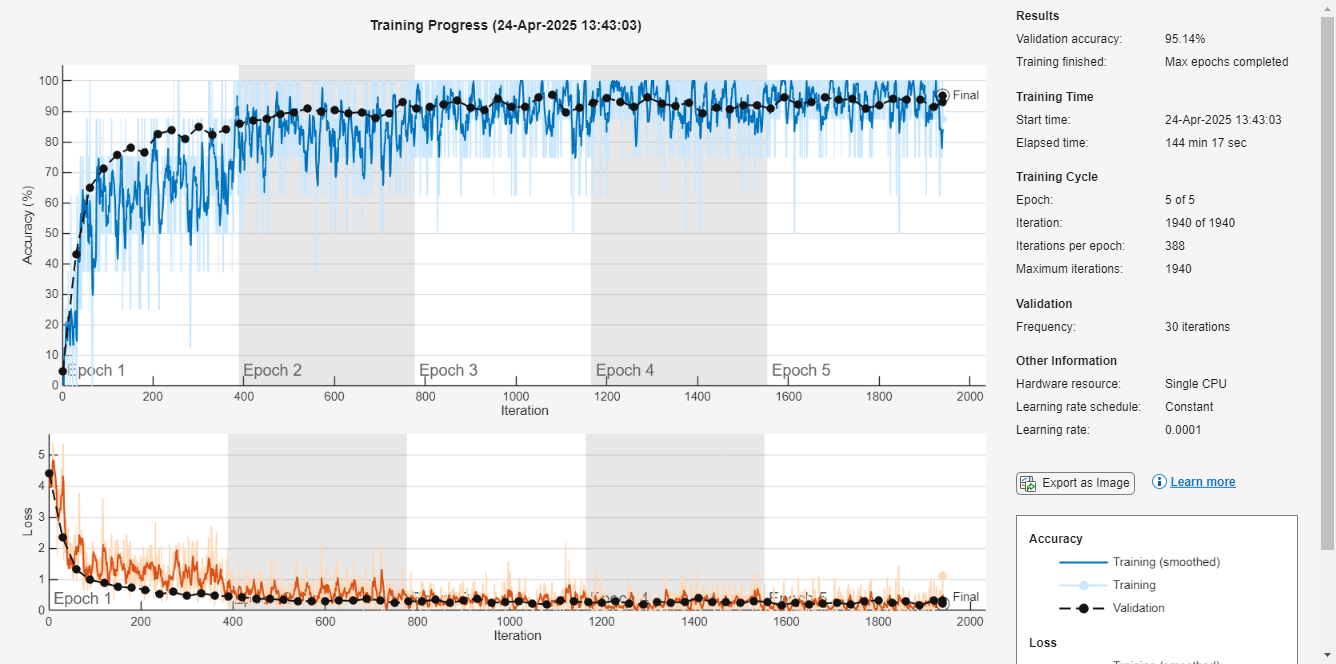

%% CNN – ResNet18 with Separate Validation Set

inputSize = [224 224 3];

% Fix label mismatch across all sets
allCats = unique([imdsTrain.Labels; imdsVal.Labels; imdsTest.Labels]);
imdsTrain.Labels = categorical(imdsTrain.Labels, allCats);
imdsVal.Labels   = categorical(imdsVal.Labels, allCats);
imdsTest.Labels  = categorical(imdsTest.Labels, allCats);

% Apply preprocessing to Train, Val, Test
imdsTrain.ReadFcn = @(filename) preprocessImage(filename, inputSize);
imdsVal.ReadFcn   = @(filename) preprocessImage(filename, inputSize);
imdsTest.ReadFcn  = @(filename) preprocessImage(filename, inputSize);

% Load ResNet18
net = resnet18;
lgraph = layerGraph(net);

% Replace last layers for our custom classes
numClasses = numel(categories(imdsTrain.Labels));
newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'fc_new', ...
        'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
    softmaxLayer('Name', 'softmax_new')
    classificationLayer('Name', 'output')];

lgraph = replaceLayer(lgraph, 'fc1000', newLayers(1));
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', newLayers(3));
lgraph = replaceLayer(lgraph, 'prob', newLayers(2));

% Training Options — use imdsVal for validation
options = trainingOptions('adam', ...
    'MiniBatchSize', 8, ...
    'MaxEpochs', 5, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsVal, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

% Train the network
trainedNet = trainNetwork(imdsTrain, lgraph, options);


% Evaluate on test set
YPred = classify(trainedNet, imdsTest);
YTrue = imdsTest.Labels;
cnnAccuracy = sum(YPred == YTrue) / numel(YTrue);
fprintf("✅ CNN Test Accuracy: %.2f%%\n", cnnAccuracy * 100);

✅ CNN Test Accuracy: 95.25%



%% Helper: Preprocessing Function
function img = preprocessImage(filename, targetSize)
    img = imread(filename);
    if size(img, 3) == 1
        img = cat(3, img, img, img); % convert grayscale to RGB
    elseif size(img, 3) == 4
        img = img(:, :, 1:3); % drop alpha or CMYK channel
    end
    img = imresize(img, targetSize(1:2));
end

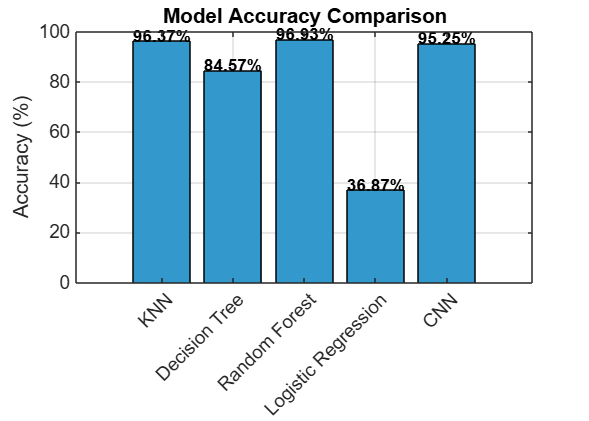

accuracyKNN = 96.37;          
accuracyDT = 84.57;          
accuracyRF = 96.93;           
accuracyLR = 36.87;           
accuracyCNN = 95.25;  

accuracies = [accuracyKNN, accuracyDT, accuracyRF, accuracyLR, accuracyCNN];
models = {'KNN', 'Decision Tree', 'Random Forest', 'Logistic Regression', 'CNN'};

figure('Position', [100, 100, 700, 500]);  % Bigger graph window
bar(accuracies, 'FaceColor', [0.2 0.6 0.8]);
set(gca, 'XTickLabel', models, 'XTickLabelRotation', 45, 'FontSize', 12);
ylabel('Accuracy (%)');
title('Model Accuracy Comparison');
ylim([0 100]);
grid on;

for i = 1:length(accuracies)
    text(i, accuracies(i) + 2, sprintf('%.2f%%', accuracies(i)), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'FontSize', 11);
end